% 分类查询数据
% 此示例显示如何按以下方式对查询数据进行分类：
% 产生 Kd 树，进行 k 最近邻搜索。
% 为每个查询点分配其各自最近邻居中具有最高表示的类。
clear

## Step 1: 根据 Fisher iris 数据的最后两列对新点进行分类。仅使用最后两列可以更轻松地绘制。

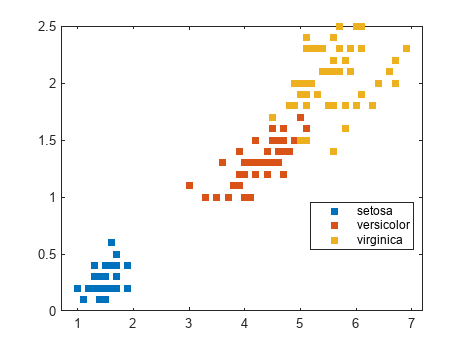

load fisheriris
x = meas(:,3:4);
figure;
gscatter(x(:,1),x(:,2),species)
legend('Location','best')

## Step 2: 准备一个 Kd 树最近邻搜索器模型。

Mdl = KDTreeSearcher(x)

Mdl =   KDTreeSearcher with properties:

       BucketSize: 50
         Distance: 'euclidean'
    DistParameter: []
                X: [150×2 double]


% Mdl 是一个 KDTreeSearcher 模型。
% 默认情况下，它用于搜索邻居的距离度量是欧几里得距离。

## Step 3: 对一个新点进行分类

绘制新点。新点的两个坐标是5和 1.45

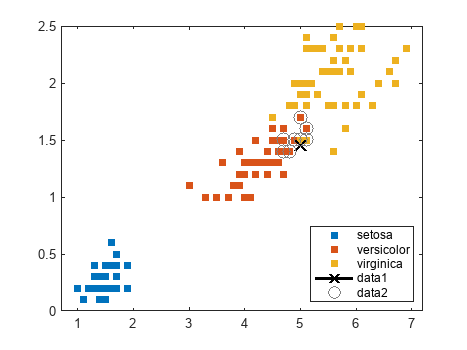

newpoint = [5 1.45];
line(newpoint(1),newpoint(2),'marker','x','color','k',...
    'markersize',10,'linewidth',2)

% 找到最接近新点的 10 个样本点。
[n,d] = knnsearch(Mdl,newpoint,'k',10);
line(x(n,1),x(n,2),'color',[.5 .5 .5],'marker','o',...
    'linestyle','none','markersize',10)


% knnsearch 似乎只找到了最近的八个邻居。事实上，这个特定的数据集包含重复的值。
x(n,:)

ans =     5.0000    1.5000
    4.9000    1.5000
    4.9000    1.5000
    5.1000    1.5000
    5.1000    1.6000
    4.8000    1.4000
    5.0000    1.7000
    4.7000    1.4000
    4.7000    1.4000
    4.7000    1.5000



% 重新画图，使轴相等，以便计算出的距离与绘图轴上的表观距离相等，然后放大以更好地查看邻居。
figure;
gscatter(x(:,1),x(:,2),species)  % 重新画图
line(newpoint(1),newpoint(2),'marker','x','color','k',...
    'markersize',10,'linewidth',2)
xlim([4.5 5.5]);
ylim([1 2]);
axis square

% 显示点坐标
fprintf('\n%s\n','1个数据点坐标如下');

1个数据点坐标如下


disp(newpoint);

    5.0000    1.4500



% 找出 10 个邻居的类别。
fprintf('\n%s\n','kNN计算的该点的占每类比例')

kNN计算的该点的占每类比例


tabulate(species(n))

       Value    Count   Percent
   virginica        2     20.00%
  versicolor        8     80.00%


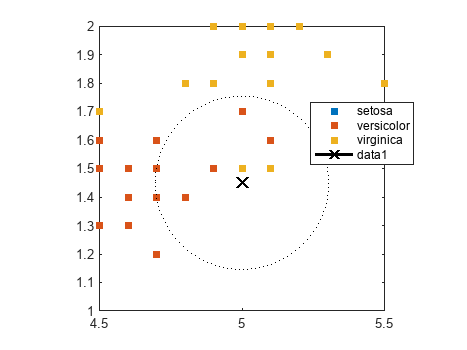

% 使用基于 10 个最近邻点的多数票的规则，您可以将此新点归类为杂色点。


% 通过在邻居组周围画一个圆圈来直观地识别邻居。根据新点的位置定义圆的中心和直径。
ctr = newpoint - d(end);
diameter = 2*d(end);
% 在 10 个最近的邻居周围画一个圆圈。
h = rectangle('position',[ctr,diameter,diameter],...
    'curvature',[1 1]);
h.LineStyle = ':';

## Step 4: 对三个新点进行分类

使用相同的数据集，找到三个新点的 10 个最近邻。

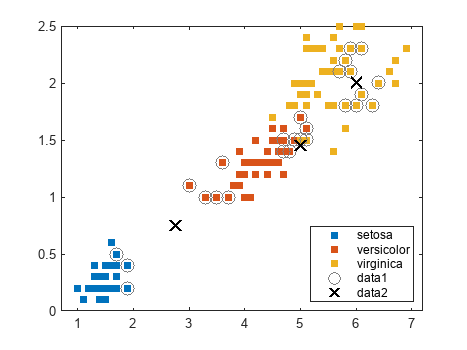

figure
newpoint2 = [5 1.45;6 2;2.75 .75];
gscatter(x(:,1),x(:,2),species)
legend('location','best')
[n2,d2] = knnsearch(Mdl,newpoint2,'k',10);
line(x(n2,1),x(n2,2),'color',[.5 .5 .5],'marker','o',...
    'linestyle','none','markersize',10)
line(newpoint2(:,1),newpoint2(:,2),'marker','x','color','k',...
    'markersize',10,'linewidth',2,'linestyle','none')


% 显示点坐标
fprintf('\n%s\n','三个数据点坐标如下')

三个数据点坐标如下


disp(newpoint2);

    5.0000    1.4500
    6.0000    2.0000
    2.7500    0.7500



% 为每个新点找出 10 个最近邻的类别。
fprintf('\n%s\n','kNN计算的每个点的占每类比例')

kNN计算的每个点的占每类比例


tabulate(species(n2(1,:)))

       Value    Count   Percent
   virginica        2     20.00%
  versicolor        8     80.00%


tabulate(species(n2(2,:)))

      Value    Count   Percent
  virginica       10    100.00%


tabulate(species(n2(3,:)))

       Value    Count   Percent
  versicolor        7     70.00%
      setosa        3     30.00%



% 给出具体的分类
cc={};
for nn=1:3
    c1=tabulate(species(n2(nn,:)));
    [a,b]=max(cell2mat(c1(:,2)));  % 投票法找到最大个数对应的类别
    cc=[cc; c1(b,1)]; % 存到cc
end
fprintf('\n%s\n','kNN计算的每个点的最后类别')

kNN计算的每个点的最后类别


disp(cc)

    {'versicolor'}
    {'virginica' }
    {'versicolor'}

